# Ejercicio


$$y''-4y=0$$


a=0;
b=1;
ya=1;
yb=3;

n=100; %Número de puntos totales
h=(b-a)/(n+1) %El denominador es el número de intervalos, es el total de puntos, -2 frontera +1 intervalo externo.
%h=0.01;
%n=(b-a)/h-1;
D=diag(2*ones(1,n));
DK=diag(-1*ones(1,n-1),1);

M=D+DK+DK';

%Aqui hacemos el ajuste
c=4*h^2; %esta constante se modifica dependiendo del resultado que nos dio a mano
C=diag(c*ones(1,n));
M=M+C;

b=zeros(n,1);
b(1)=ya;
b(end)=yb;



yGS=GaussSeidel4(M,b);
t=a:h:b; %nos da n puntos

plot(t,[ya;yGS;yb])
hold off
%tridiag
e=-1*ones(1,n);
f=2*ones(1,n);
g=-1*ones(1,n);

c=4*h^2;
C=c*ones(1,n);
f=f+C;


r=zeros(n,1);
r(1)=ya;
r(end)=yb;

yTr=Tridiag(e,f,g,r);
t=a:h:b;

plot(t,[ya;yTr;yb])


$$y''+2y'-8y=0$$



$$y(0)=1; y(1)=0$$


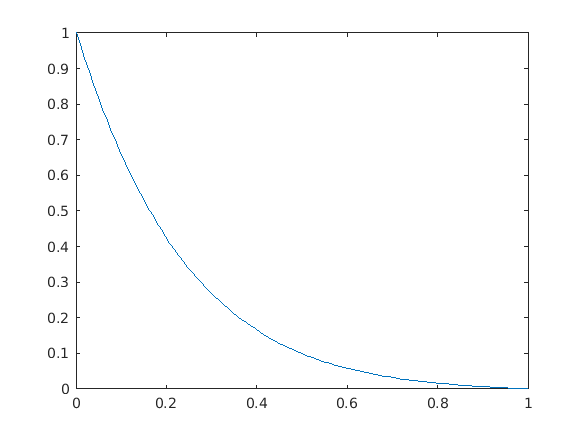

a=0;
b=1;
ya=1;
yb=0;

n=100; %Número de puntos totales
h=(b-a)/(n+1); 
%h=0.01;
%n=(b-a)/h-1;
D=diag(2*ones(1,n));
DK=diag(-1*ones(1,n-1),1);

M=D+DK+DK';

%Aqui hacemos el ajuste de y_i
c=8*h^2; %esta constante se modifica dependiendo del resultado que nos dio a mano
C=diag(c*ones(1,n));
M=M+C;

%Aqui hacemos el ajuste de y_i+1, y_i-1
c=h; %esta constante se modifica dependiendo del resultado que nos dio a mano
C=diag(c*ones(1,n-1),1);
M=M-C+C';


b=zeros(n,1);
b(1)=ya;
b(end)=yb;



yGS=GaussSeidel4(M,b);
t=a:h:b; %nos da n puntos

plot(t,[ya;yGS;yb])
hold off

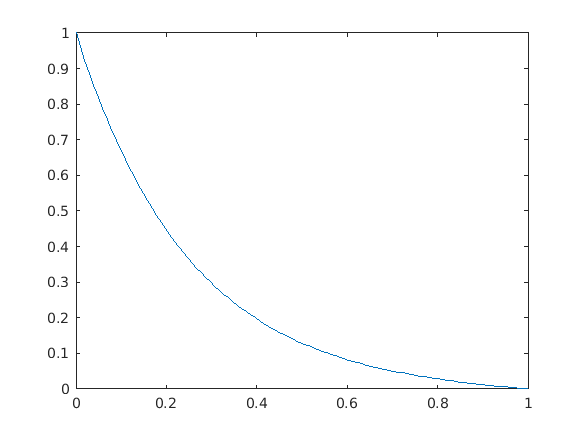


%tridiag
e=-1*ones(1,n);
f=2*ones(1,n);
g=-1*ones(1,n);

c=8*h^2;
C=c*ones(1,n);
f=f+C;

c=h;
C=c*ones(1,n);

e=e+C;
g=g-C;

r=zeros(n,1);
r(1)=ya-h;
r(end)=yb;

yTr=Tridiag(e,f,g,r);
t=a:h:b;

plot(t,[ya;yTr;yb])

y_i=diag(c*ones(1,n));

y_i+1=diag(c*ones(1,n-1),1);

y_i-1=diag(c*ones(1,n-1),-1);

## Problema de temperatura

hp=0.01;    Ta=20;
x0=0;   xf=10;
T0=40;  Tf=200;

%Gauss
h=2;
n=(xf-x0)/h-1;
D=diag(2*ones(1,n));
DK=diag(-1*ones(1,n-1),1);

M=D+DK+DK';

a=hp*h^2;
A=diag(a*ones(1,n));
M=M+A;

b=hp*h^2*Ta*ones(n,1);
b(1)=b(1)+T0;
b(end)=b(end)+Tf;

x=x0:h:xf;
T=GaussSeidel4(M,b);
plot(x,[T0;T;Tf])
hold off
%Tridiag
e=-1*ones(1,n);
f=2*ones(1,n);
g=-1*ones(1,n);

c=hp*h^2;
C=c*ones(1,n);
f=f+C;

r=hp*h^2*Ta*ones(n,1);
r(1)=T0+r(1);

r(end)=r(end)+Tf;

triT=Tridiag(e,f,g,r);

plot(x,[T0;triT;Tf])